## Bisection_Method code

### Input

f = @(x) x^2 - 5*x + 3; % the function
n=10;      % numer of iteration
a=0;        %interval start value
b=3;        %interval end value
h=(b-a)/n;   % step size
e = 0.0001;

 x=a:h:b;
y=zeros(size(x));


y(1)=0; 

### algebraic Eq. $x^2 -5x+3=0$

if f(a)*f(b)<0
    for i=1:n
        c = (a+b)/2;
        fprintf('P%d = %.4f\n',i,c)
        if abs(c-b) < e || abs(c-a) < e
            break
        end
        if f(a)*f(c)<0
            b = c;
        elseif f(b)*f(c)<0
            a = c;
        end
    end
else
    disp('No root between given brackets')
end

P1 = 1.5000
P2 = 0.7500
P3 = 0.3750
P4 = 0.5625
P5 = 0.6562
P6 = 0.7031
P7 = 0.6797
P8 = 0.6914
P9 = 0.6973
P10 = 0.6943


### Visualization:

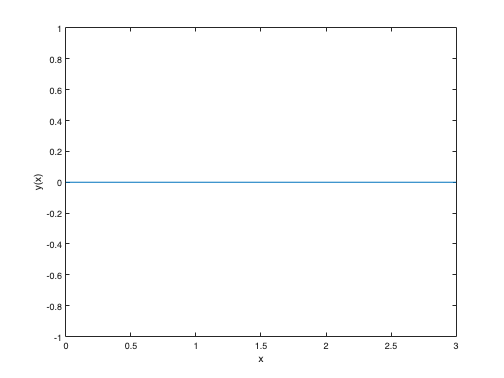

figure(1)
plot(x,y)
xlabel('x')
ylabel('y(x)')